# Import data from spreadsheet

Script for importing data from the following spreadsheet:

## Setup the Import Options and import the data

excelFilePath = "C:\Users\harjo\Desktop\runs.xlsx";
sheetname = "2NM";
opts = spreadsheetImportOptions("NumVariables", 27);

% Specify sheet and range
opts.Sheet = sheetname;
opts.DataRange = "A75:AA5878";
opts.VariableUnitsRange = "A74:AA74";

% Specify column names and types
opts.VariableNames = ["speed", "time", "elapsedDistance", "lateralAcceleration", "longitudinalAcceleration", "gear", "gearRatio", "engineSpeed", "torque", "power", "downForce", "dragForce", "tractionControl", "throttlePosition", "brakePosition", "cornerRadius", "sectorIndex", "maximumCornerSpeed", "loadSensitiveLatGrip", "loadSensitiveLongGrip", "yawangle", "yawvelocity", "yawacceleration", "xposition", "yposition", "trackelevation", "fz"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
% Import the data
rawDriveCycleTable = readtable(excelFilePath, opts, "UseExcel", false)

rawDriveCycleTable = 5804×27 table
    speed       time       elapsedDistance    lateralAcceleration    longitudinalAcceleration    gear    gearRatio    engineSpeed    torque     power     downForce    dragForce    tractionControl    throttlePosition    brakePosition    cornerRadius    sectorIndex    maximumCornerSpeed    loadSensitiveLatGrip    loadSensitiveLongGrip    yawangle    yawvelocity    yawacceleration     xposition     yposition    trackelevation      fz  
    ______    _________    

% Resample the data so that the time step is uniform, which is required for
% the drive cycle block.
rawDriveCycleTable.time = seconds(rawDriveCycleTable.time);
driveCycleNonUniformTimeTable = table2timetable(rawDriveCycleTable,'RowTimes','time');

% Retime timetable
driveCycleTimeTable = retime(driveCycleNonUniformTimeTable,'regular','linear',...
    'TimeStep',milliseconds(10))

driveCycleTimeTable = 10893×26 timetable
      time      speed     elapsedDistance    lateralAcceleration    longitudinalAcceleration    gear    gearRatio    engineSpeed    torque    power     downForce    dragForce    tractionControl    throttlePosition    brakePosition    cornerRadius    sectorIndex    maximumCornerSpeed    loadSensitiveLatGrip    loadSensitiveLongGrip     yawangle      yawvelocity    yawacceleration     xposition     yposition    trackelevation      fz  
    ________    ______    <s

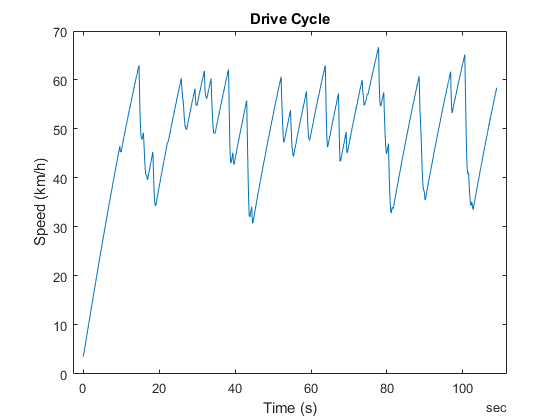

plot(driveCycleTimeTable.time,driveCycleTimeTable.speed);
title('Drive Cycle')
xlabel('Time (s)')
ylabel('Speed (km/h)')

## Setup Variable for Simulink Drive Cycle Sim

drivecycle.time = seconds(driveCycleTimeTable.time);
drivecycle.signals.values = driveCycleTimeTable.speed;